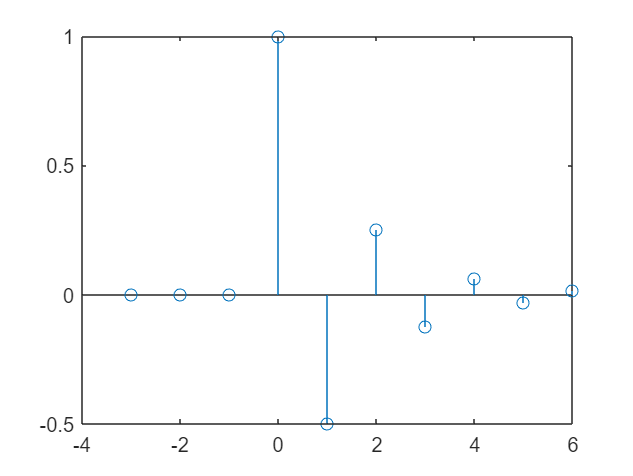

% x1[n]
n = -3:6;
u = (n>=0);
x1 = (-0.5).^n.*u;
stem(n,x1)

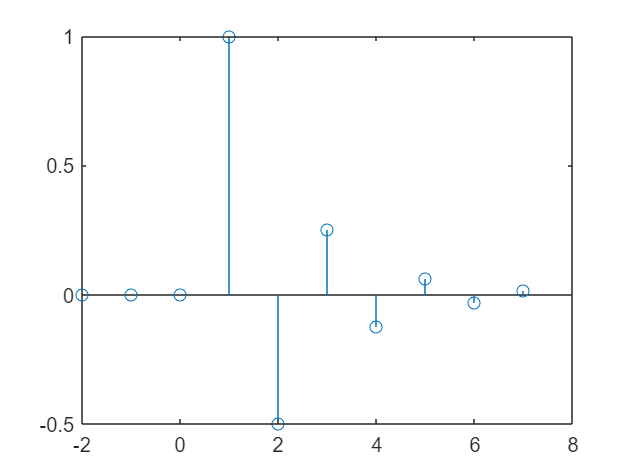

x2 = (-0.5) .^ (n-1) .* u;
stem(n2,x1)

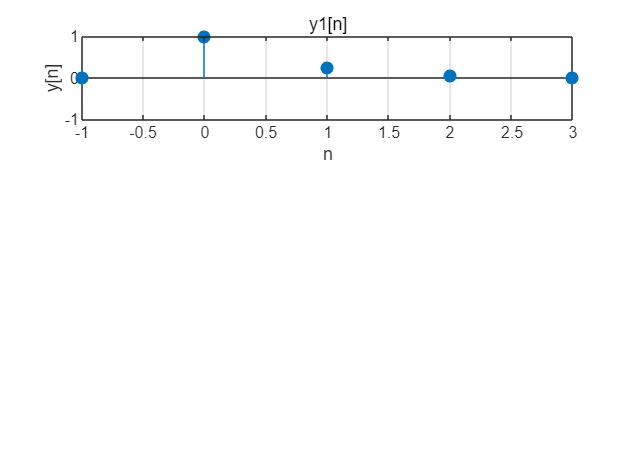

% y1[n]
n1_init = 0.5 .* n;
n1_init(rem(n1_init, 1) ~= 0) = [];

y1 = x1;
ind = 1 : length(y1);
y1(rem(ind, 2) ~= 0) = [];

subplot(3, 1, 1);
stem(n1_init, y1, "filled");
axis([-1, 3, -1, 1]);
title("y1[n]");
xlabel("n")
ylabel("y[n]");
grid on;

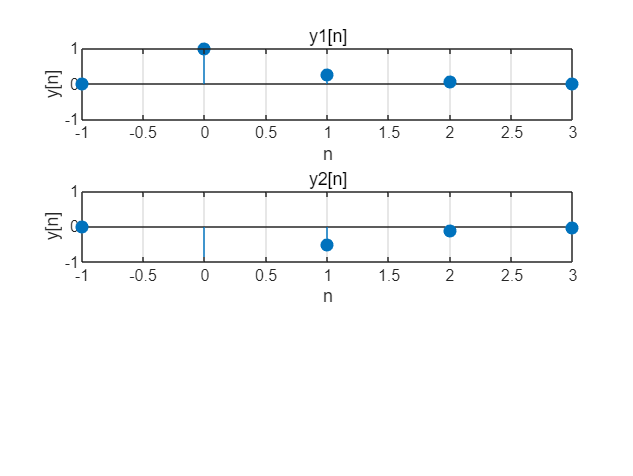

y2 = x2;
ind2 = 1 : length(y2);
y2(rem(ind2, 2) ~= 0) = [];

subplot(3, 1, 2);
stem(n1_init, y2, "filled");
axis([-1, 3, -1, 1]);
title("y2[n]");
xlabel("n")
ylabel("y[n]");
grid on;

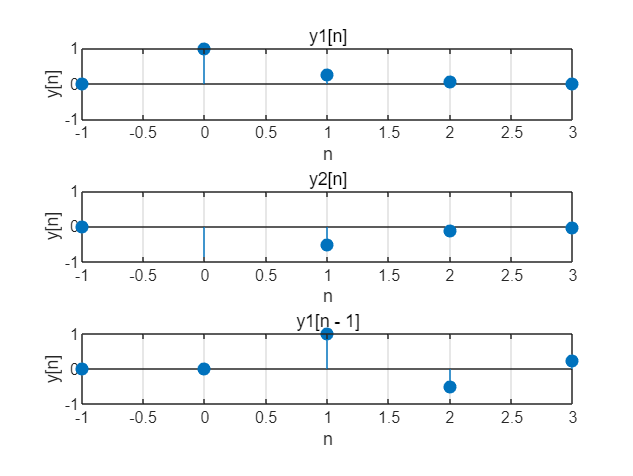

n3 = n + 1;
y3 = x1;

subplot(3, 1, 3);
stem(n3, y3, "filled");
axis([-1, 3, -1, 1]);
title("y1[n - 1]");
xlabel("n")
ylabel("y[n]");
grid on;